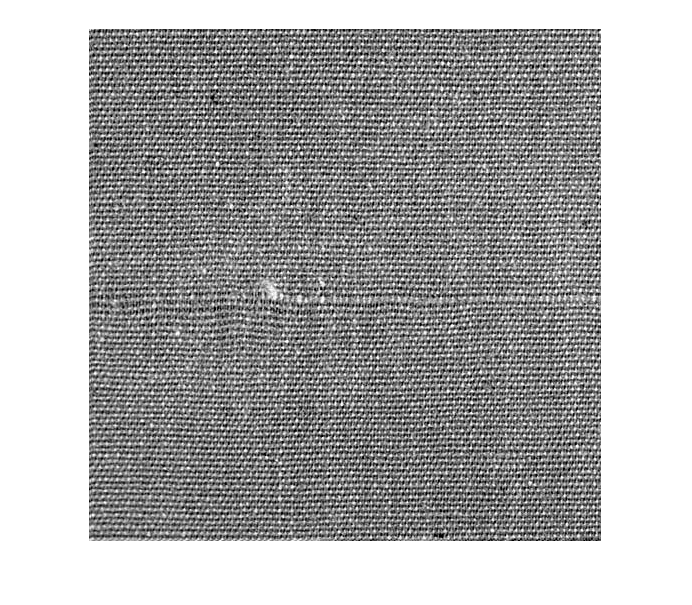

% Martedi 03 Novembre 2020 - Mercoledi 04 Novembre 2020
% Corso di Elaborazione dei Segnali e Immagini
% Docente: Ilaria Boscolo Galazzo 
% Docente Coordinatore: Marco Cristani
% Tutor lab: Christian Joppi 
% LAB2 - parte 2

clear all
close all
clc

%Esercizio 1 - Cross-correlazione 2D normalizzata per trovare difetti su tessuti
B= rgb2gray(imread('tex1.jpg'));
[R,C]=size(B);

%Aumento contrasto con imadjust con stretchlim che imposta automaticamente
%la soglia minima del contrasto
A = imadjust(B,stretchlim(B),[]);
figure;
imshow(A);


%Ricerca dimensione pattern ideale
i = 0;
j = 1;
inizio = 1;
fine = 8;
times =  linspace(inizio,fine,8); 

%Ricerca dei massimi  di correlazione con funzione graycoprops
offsets0 = [zeros(40,1) (1:40)'];
glcm = graycomatrix(A, 'offset', offsets0);
stats = graycoprops(glcm,'Contrast Correlation');
figure, plot([stats.Correlation]);
title('Texture Correlation as a function of offset');
xlabel('Horizontal Offset')
ylabel('Correlation')    

%Ricerca dei massimi
Massimi = findpeaks(stats.Correlation);

%Pulizia dei massimi non rilevanti
Massimi = Massimi(3:length(Massimi));

%Massimi rilevanti ordinati in ordine decrescente
Massimi = sort(Massimi, 'descend');

%Prendo dal primo posto dell'array il valore corrispondente alla dimensione
%ottimale da utilizzare come pattern
maxValue = Massimi(1);

%Prendo la dimensione ottimale del pattern
patternDimension = find(stats.Correlation == maxValue);

% Definisco i pattern con la dim ottimale ricavata sopra
%Facciamo 8 pattern , 2 per ogni angolo
pattern1 = A(1 : patternDimension, 1 : patternDimension);                   %Alto a sinistra
pattern2 = A(R - patternDimension : R - 1, C - patternDimension : C - 1);     %Basso a destra
pattern3 = A(R - patternDimension : R - 1, 1 : patternDimension);               %Basso a sinistra
pattern4 = A(1 : patternDimension, C - patternDimension : C - 1);           %Alto a destra
pattern5 = A(2 : patternDimension + 1, 2 : patternDimension + 1);
pattern6 = A(R - patternDimension - 1 : R - 2, C - patternDimension - 1 : C - 2 );
pattern7 = A(R - patternDimension - 1 : R - 2, 2 : patternDimension + 1 );
pattern8 = A(2 : patternDimension + 1, C - patternDimension - 1 : C - 2);
pattern9 = A(3 : patternDimension + 2, 3 : patternDimension + 2);
pattern10= A(3 : patternDimension + 2, C - patternDimension - 2 : C - 3);

% Calcolo la xcorr-2D (normalizzata). Size = N+M-1
c1 = normxcorr2(pattern1,A); 
c2 = normxcorr2(pattern2,A);
c3 = normxcorr2(pattern3,A);
c4 = normxcorr2(pattern4,A);
c5 = normxcorr2(pattern5,A);
c6 = normxcorr2(pattern6,A);
c7 = normxcorr2(pattern7,A);
c8 = normxcorr2(pattern8,A);
c9 = normxcorr2(pattern9,A);
c10= normxcorr2(pattern10,A);

% From MATLAB Help:
% C = normxcorr2(TEMPLATE,A) computes the normalized cross-correlation of
%     matrices TEMPLATE and A. The matrix A must be larger than the matrix
%     TEMPLATE for the normalization to be meaningful. The values of TEMPLATE
%     cannot all be the same. The resulting matrix C contains correlation
%     coefficients and its values may range from -1.0 to 1.0.

c = (c1 + c2 + c3 + c4 + c5 + c6 + c7 + c8 + c9 + c10) / 10; % calcolo media (537x537)
display(mean(abs(c),'all'));

    0.0538



%Prova parametrizzazione raggio disk strel

if mean(abs(c),'all') < 0.07
    sizeofdisk = 1;
else
    sizeofdisk = 2;
end

[altezza, larghezza] = size(c);
scarto = (altezza-500)/2;
scarto = cast(scarto,'int32');
if rem(altezza,2) ~= 0
    c = c(scarto:(end-scarto),scarto:(end-scarto));
else
    c = c(scarto:(end-(scarto+1)),scarto:(end-(scarto+1)));
end

figure, surf(abs(c)), shading flat
figure, imagesc(abs(c)), colorbar
c = abs(c);
display(c);

c =     0.1053    0.0850    0.0654    0.0881    0.1041    0.1051    0.1012    0.0855    0.0725    0.0823    0.0843    0.0851    0.0912    0.0774    0.0694    0.0874    0.0955    0.0971    0.0977    0.0712    0.0601    0.0847    0.0967    0.1010    0.0931    0.0645    0.0576    0.0812    0.0933    0.0901    0.0849    0.0742    0.0722    0.0900    0.0945    0.0895    0.0882    0.0672    0.0589    0.0844    0.1003    0.0961    0.0859    0.0614    0.0587    0.0710    0.0641    0.0647    0.0736    0.0506
    0.0626    0.0368    0.0277    0.0701    0.0816    0.0650    0.0596    0.0476    0.0393    0.0582    0.0647    0.0591    0.0577    0.0342    0.0248    0.0546    0.0701    0.0704    0.0687    0.0348    0.0177    0.0529    0.0704    0.0697    0.0608    0.0295    0.0221    0.0524    0.0608    0.0467    0.0423    0.0296    0.0318    0.0653    0.0674    0.0505    0.0452    0.0163    0.0106    0.0488    0.0581    0.0506    0.0403    0.0163    0.0255    0.0537    0.0445    0.0351    0.0321    0


% Graythreshold
lv = graythresh(c);
maskt = c > (lv);
display(size(maskt));

   500   500



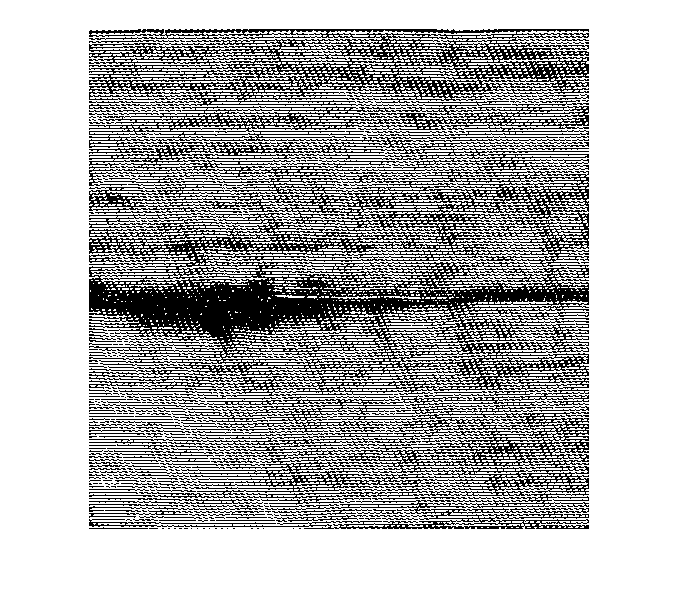

figure; 
imshow(maskt);

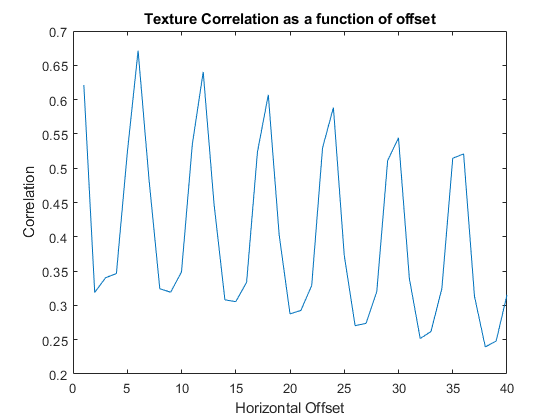

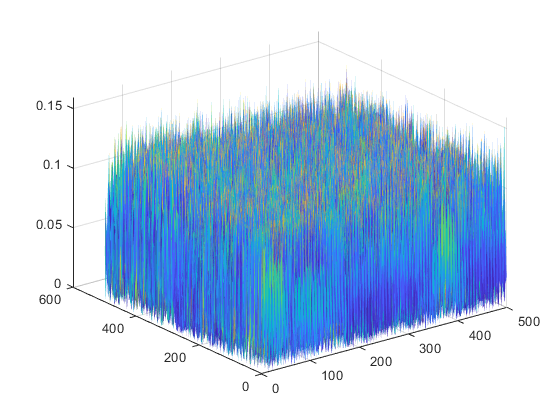

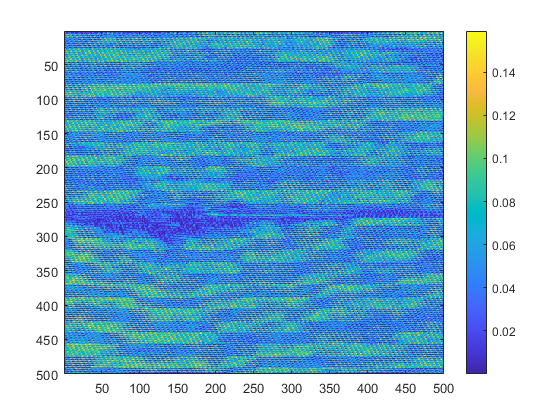

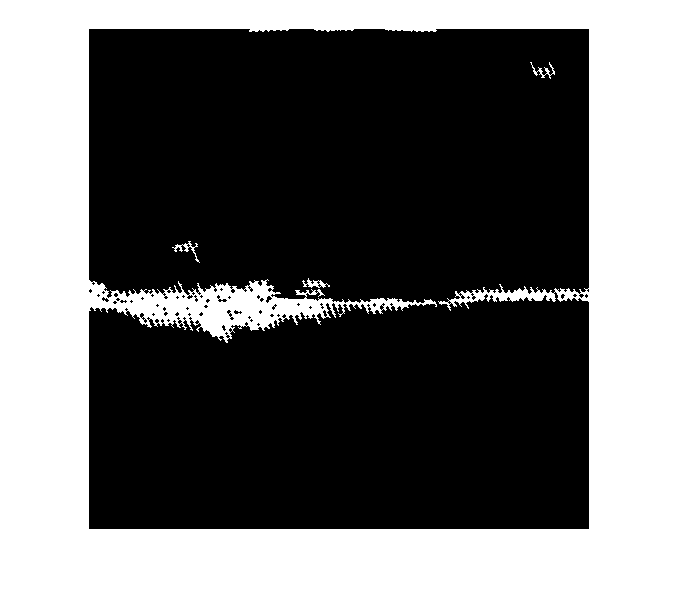


se3 = strel("disk", sizeofdisk);
maskt = imdilate(maskt , se3);
maskt = imcomplement(maskt);
CC = bwconncomp(maskt);         %Componenti iù grandi connessi
maskt = bwareafilt(maskt,CC.Connectivity,'largest');
imshow(maskt);

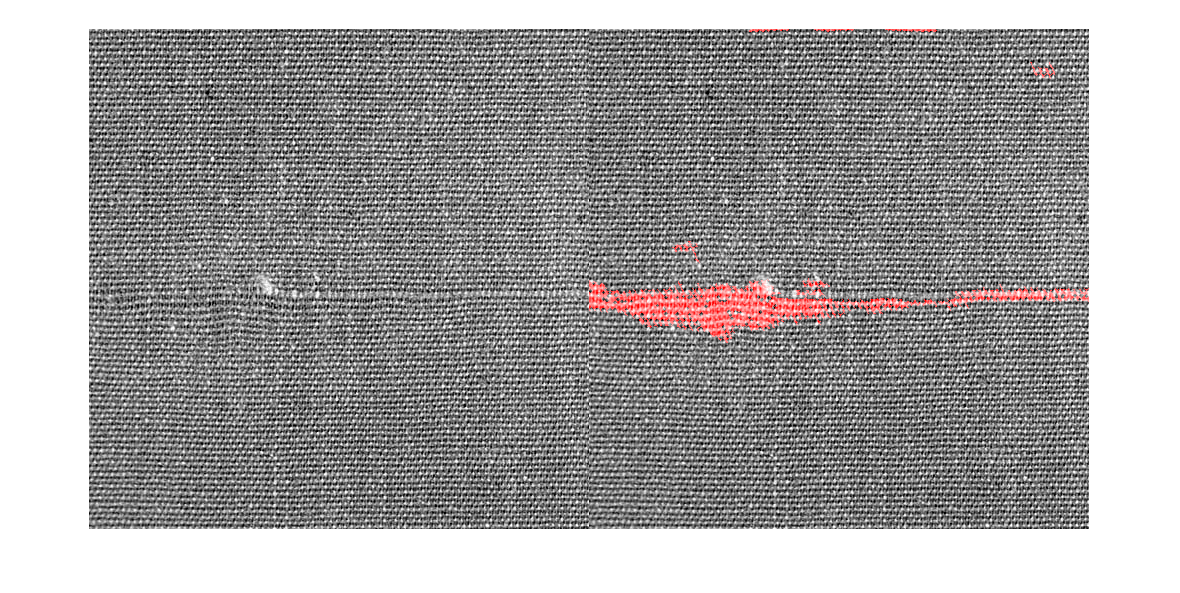

A=A(6:end-7,6:end-7);           % Passo da 512x512 a 500x500
A1 = A;
A1(maskt)=255;

Af=cat(3,A1,A,A);
figure;
imshowpair(A,Af,'montage')